## Mumax Rider:Dispersion relation 2023.6.14

## 0 Preparation Work

Refresh

clear,clc 

Detect the folder name

%Live Editor cannot read the path normally here just input the folder name
%filePath = mfilename('fullpath');
%[ProjectPath, ~, ~] = fileparts(filePath);
ProjectPath='D:\Workspace\MatLabData\';
disp("Checked, the script is now running in the folder "+ProjectPath+"\n");

Checked, the script is now running in the folder D:\Workspace\MatLabData\\n


Check the essential function

if exist(ProjectPath+"\read_ovf.m", 'file') == 2
    disp('read_ovf.m function checked \n');
else
    disp('read_ovf.m lost \n');
end

read_ovf.m function checked \n



if exist(ProjectPath+"\plot_dispersion.m", 'file') == 2
    disp('plot_dispersion.m function checked \n');
else
    disp('plot_dispersion.m lost \n');
end

plot_dispersion.m function checked \n



if exist(ProjectPath+"\assignN.m", 'file') == 2
    disp('assignN.m function checked \n');
else
    disp('assignN.m lost \n');
end

assignN.m function checked \n


Setup a output folder for result and the name for the script

OutputPath  = ProjectPath+"\output\";
scriptName  = "cellchain"; % Custom  the script and output folder name
if ~isfolder(OutputPath) %Create the folder if not exist.
    mkdir(OutputPath);
end

## 1 Create a script for run

Input the name of template and auto check if exists

%Set a template folder for reading the template mumax3 script
templateName="cellchain.txt";
templatePath= ProjectPath+"\template\"+templateName;

if exist(templatePath, 'file') == 2
    disp('template checked \n');
else
    disp('template lost \n');
end

template checked \n


Fill the parameters into the template

% NUMERICAL PARAMETERS
fmax = 40e9;            % maximum frequency (in Hz) of the sinc pulse
T    = 1e-8;            % simulation time (longer -> better frequency resolution)
dt   = 1/(2*fmax);      % the sample time
dx   = 4e-9;            % cellsize
nx   = 1024;            % number of cells

%MATERIAL/SYSTEM PARAMETERS
Bz    = 0.2;        % Bias field along the z direction
A     = 13e-12;     % exchange constant
Ms    = 800e3;      % saturation magnetization
alpha = 0.05;       % damping parameter
gamma = 1.76e11;    % gyromagnetic ratio

Read the template


%Open the template path
fid = fopen(templatePath, 'r');
template = fread(fid, '*char')';
fclose(fid);

Fill in paramters

% 要替换的内容和对应的替换值
replacements = {
    '{nx}', num2str(nx);
    '{dx}', num2str(dx);
    "{A}",num2str(A);
    "{Ms}",num2str(Ms);
    '{alpha}',num2str(alpha);
    "{Bz}",num2str(Bz);
    "{fmax}",num2str(fmax);
    "{T}",num2str(T);
    "{dt}",num2str(dt);
    "{gamma}",num2str(gamma);
    % 添加更多需要替换的内容和对应的替换值
};


for i = 1:size(replacements, 1)
    template = strrep(template, replacements{i, 1}, replacements{i, 2});
end

Output the script as request name

scriptFilePath=OutputPath+scriptName+".txt";
fid = fopen(scriptFilePath, 'w');
% Write it in 
fprintf(fid, '%s', template);
fclose(fid);


## 2 Run the script

%Excute the script with mumax3 engine

command = 'mumax3 '+scriptFilePath;
status = system(command);

//mumax 3.10 [windows_amd64 go1.11.6(gc) CUDA-11.0]
//GPU info: NVIDIA GeForce RTX 3060 Laptop GPU(6143MB), CUDA Driver 12.2, cc=8.6, using cc=80 PTX
//(c) Arne Vansteenkiste, Dynamat LAB, Ghent University, Belgium
//This is free software without any warranty. See license.txt
//********************************************************************//
//  If you use mumax in any work or publication,                      //
//  we kindly ask you to cite the references in references.bib        //
//********************************************************************//
//output directory: D:\Workspace\MatLabData\\output\cellchain.out/
//starting GUI at http://127.0.0.1:35367
setgridsize(1024, 1, 1)
setcellsize(4e-09, 4e-09, 4e-09)
OutputFormat = OVF2_TEXT
enabledemag = false
Aex = 1.3e-11
Msat = 800000
alpha = 0.05
Bz := 0.2
B_ext = vector(0, 0, 0.2)
defregion(1, rect(2*4e-09, inf))
B_ext.setregion(1, vector(0.01*sinc(2*pi*40000000000*(t-1e-08/2)), 0, 0.2))
m = uniform(0, 0, 1)
autosave(m, 1.

if status == 0
    disp('mumax3 status checked');
else
    disp('mumax3 failed');
end

mumax3 status checked


## 3 Batch extract the data

dir=OutputPath+scriptName+'.out\m';
[info,data]=read_ovf(dir,0,799);

## 4 Plot the dispersion Curve

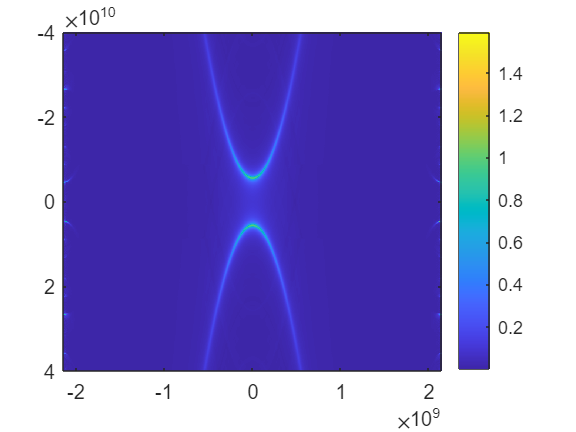

plot_dispersion(info,data,1e-8,40e9,"x")